clear all
addpath("Spiral pulley")
load("best_constant_spiral.mat"); %loading in the best constant force shape
n_steps = 2000; %shape resolution

### Initial stable condition

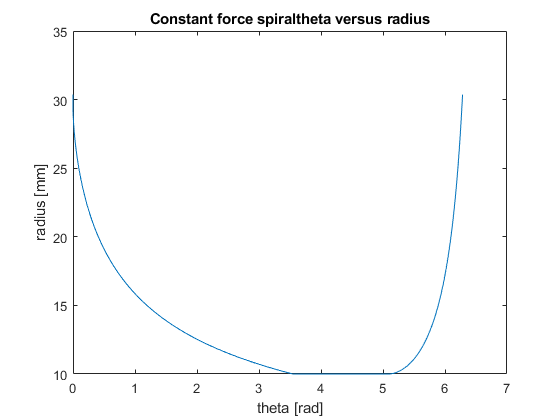

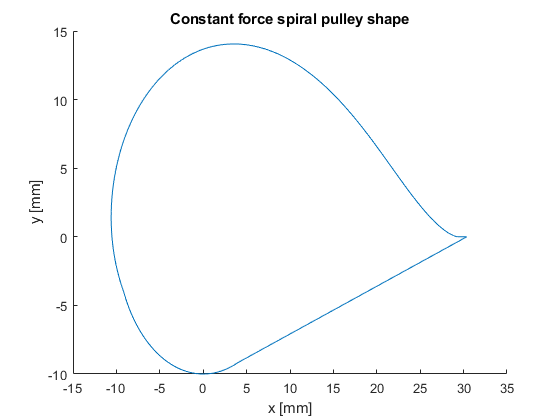

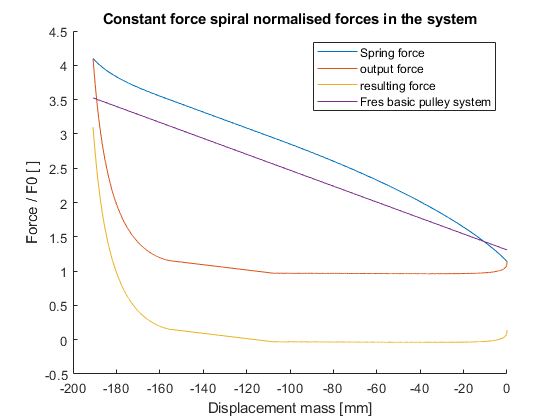

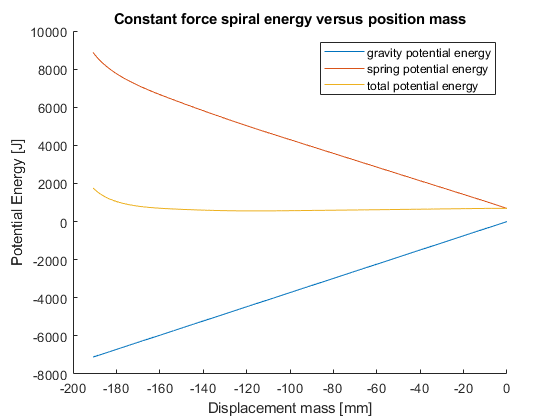

spiral =   spiral with properties:

               r1: 10
               r2: 30.3600
               F0: 37.2780
                k: 1.3150
             name: 'Constant force spiral'
                r: [1×1302 double]
            theta: [1×1302 double]
                x: [1×1302 double]
                y: [1×1302 double]
                S: 860.6541
      curve_angle: []
             x_m2: 190.7575
              x_m: [1×2001 double]
              x_s: [1×2001 double]
               rs: [1×2001 double]
              phi: [1×2001 double]
    spring_offset: 4
               Fm: [1×2001 double]
               Fs: [1×2001 double]
             Fres: [1×2001 double]
       Fm_control: [1×2001 double]
               Eg: [1×2001 double]
               Es: [1×2001 double]
             Etot: [1×2001 double]


spiral = best_spiral.plot_all(n_steps,best_spiral.spring_offset) %genenerating and plotting initial condition

## Step 1: lowering and activiation first stage

In this first step the mass is lowerd by it being pushed down by the guiding rails. At the end of the rails it has to disconnect by itself by the fact that the equilibrium position is lower than the guiding rails

Important parts about the force balance and potential energy

- Troughout the long stroke motion we must have positive pressure, negative pressure will mean disengagement of the guides

- When we reach the final end position we want to crossover to negative force -> This way the mass will lower itself 

- We want the local equilibrium point to be 10 mm lower than the crossover point (the point where the guides will be disengaged)

- Initial position

- Crossover point

- Equilibrium position

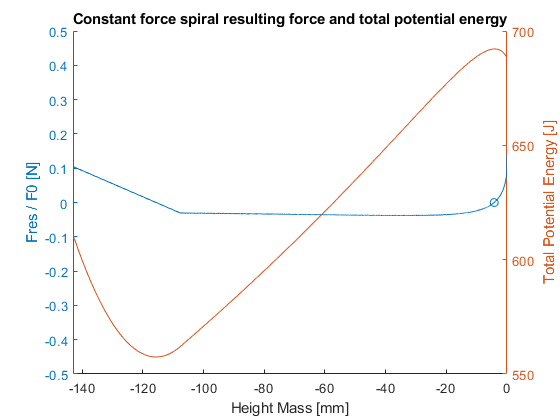

spiral = spiral.complete_analysis(n_steps,spiral.spring_offset);
fig = spiral.plot_force_energy();
x0 = find_zero(spiral.x_m, spiral.Fres); %finding zeros
yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0))) %plotting zero positions


lowered_spiral = spiral.complete_analysis(n_steps,spiral.spring_offset-5);
fig = lowered_spiral.plot_force_energy();
x0 = find_zero(lowered_spiral.x_m, lowered_spiral.Fres) %finding zeros

x0 = -130.8736

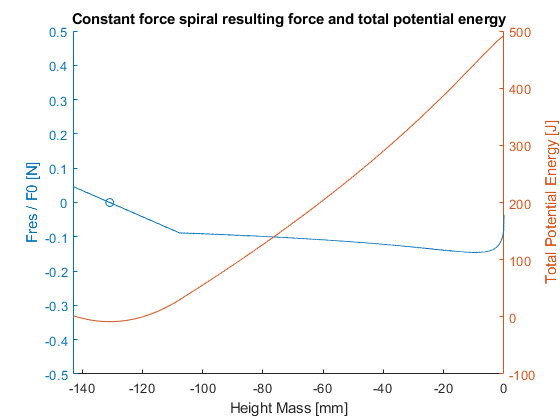

%self_lowering = x0(3) - x0(2)
%final_position = x0(3)
yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0))) %plotting zero positions

## Step 2 Transfer of mass

The mass that is on the system is lowerered to 17.658 N, this results in a high net spring force, which is undesirable. for this the spring position is decreased such that is has a lowered net positive force.

System in total has net positive force meaning that it willl return to guides 

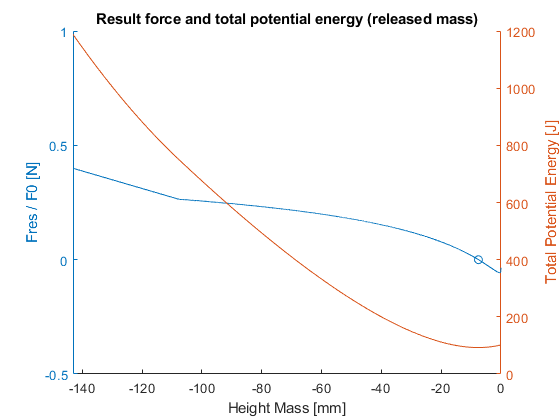

m2_spiral = lowered_spiral;
m2_spiral.F0 = 17.658; %setting decreases mass\

m2_spiral = m2_spiral.complete_analysis(n_steps,m2_spiral.spring_offset);
m2_spiral.F0 = 37.278;
fig = m2_spiral.plot_force_energy();
title('Result force and total potential energy (released mass)')
yyaxis left
ylim([-0.5 1])
x0 = find_zero(m2_spiral.x_m, m2_spiral.Fres); %finding zeros
yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0))) %plotting zero positions

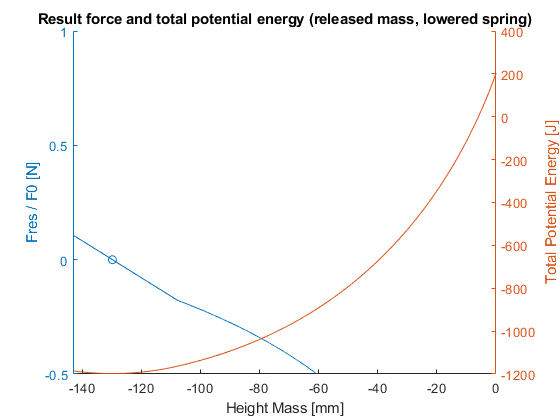


m2_spiral = lowered_spiral;
m2_spiral.F0 = 17.658; %setting decreases mass
m2_spiral = m2_spiral.complete_analysis(n_steps,m2_spiral.spring_offset-30);
fig = m2_spiral.plot_force_energy();
title('Result force and total potential energy (released mass, lowered spring)')
yyaxis left
ylim([-0.5 1])
x0 = find_zero(m2_spiral.x_m, m2_spiral.Fres); %finding zeros
yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0))) %plotting zero positions

## Step 3: Raising and retrieving 

In step 2 large part of the stroke could be performed however at the end the positive force is not strong enough and the system has to be adjusted mid long stroke such that the force stays positive 

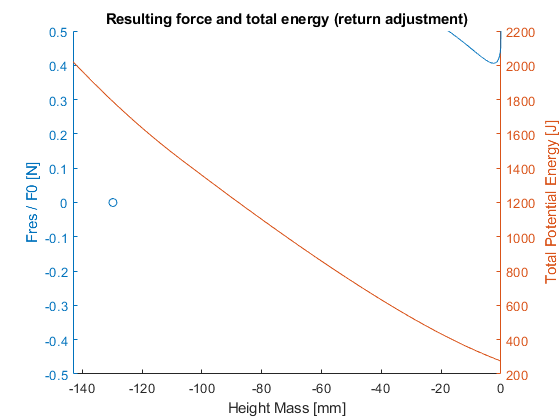

raising_spiral = m2_spiral.complete_analysis(n_steps,spiral.spring_offset+3);
fig = raising_spiral.plot_force_energy();
title('Resulting force and total energy (return adjustment)')
%x0 = find_zero(raising_spiral.x_m, raising_spiral.Fres) %finding zeros
%self_lowering = x0(3) - x0(2)
yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0))) %plotting zero positions

## Part 2

engaging and retrieving is the same as the above but then in reverse order

### Potential optimization

To minimize pressure on the guiding rails the spring tension can be adjusted trough the motion such that is is sufficiently low

## Functions

function x0 = find_zero(x,y)
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Approximate Zero-Crossing Indices Of Argument Vector
    dy = zci(y);                                                            % Indices of Approximate Zero-Crossings
    for k1 = 1:size(dy,1)-1
        b = [[1;1] [x(dy(k1)); x(dy(k1)+1)]]\[y(dy(k1)); y(dy(k1)+1)];      % Linear Fit Near Zero-Crossings
        x0(k1) = -b(1)/b(2);                                               % Interpolate ;Exact’ Zero Crossing
        %mb(:,k1) = b;                                                       % Store Parameter Estimates (Optional)
    end
end
